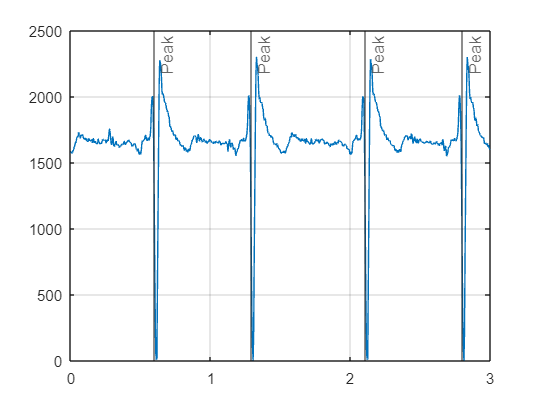

heartRate = 0.6921

heartRate = 0.8161

heartRate = 0.6921

heartRate = 0.8161

heartRate = 0.6921

heartRate = 0.8161

heartRate = 0.6921

heartRate = 0.8161

heartRate = 0.6921

heartRate = 0.8161

heartRate = 0.6921

heartRate = 0.8161

heartRate = 0.6881

heartRate = 0.0080

heartRate = 0.8121

heartRate = 0.6881

heartRate = 0.8201

heartRate = 0.6881

heartRate = 0.8201

heartRate = 0.6881

heartRate = 0.8321

heartRate = 0.6881

heartRate = 0.8201

heartRate = 0.6881

heartRate = 0.8201

heartRate = 0.6881

heartRate = 0.8201

heartRate = 0.6881

heartRate = 0.8201

heartRate = 0.6881

heartRate = 0.8201

heartRate = 0.6881

heartRate = 0.8201

heartRate = 0.6881

heartRate = 0.8201

heartRate = 0.6841

heartRate = 0.8201

heartRate = 0.6841

heartRate = 0.8201

heartRate = 0.6881

clear
close all

T_A = 4e-3;
f_A = 1/T_A;


data = transpose(load("uC_data.mat").dataOut(:,2));
BUFFERSIZE = length(data);
t = linspace(0,30,BUFFERSIZE);
heartTime = 0;

peakDetected = false;

figure
plot(t, data)
xlim([0 3])
grid
n= 1;
for i=2:BUFFERSIZE
    if data(i) <  1000
        if(data(i) < data(i-1))
            if peakDetected == false
                heartTime(:,n) = t(i); 
                xline(t(i), '-','Peak')
                peakDetected = true;
                if(n>1)
                    heartRate = heartTime(n) - heartTime(n-1)
                end
                n = n+1;
            end
        elseif data(i) > data(i-1)
            peakDetected = false;
        end
    end
end